# Time lapsed tSNE plots of syllables

### Set configurations

% Query for syllables to be retrieved
birdname = 'br173gr56';
days = [86];
syls = ['d']; % 'all' or syllable labels
min_max_duration = [20 150]; % select syls only with this min and max duration in milliseconds

% Spectrogram parameters
overlap_windowsize = [0.9 10]; % spectrogram windows: pct overlap, bin size (msec)
short_syl_windows = calcNumWindows(min_max_duration(1),overlap_windowsize); % # of windows of shortest syllable

Number of time bins: 11


which_windows = [1 which_windows];%['end-' num2str(numWindows) '_to_end'];

% t-SNE parameters
tsne_setting = 'custom' % 'default' or 'custom' tsne function settings
seed = rng(42);
perp = 120;
exg = 5; 

% Directory for saving output files


% create parameter structures for saving and input arguments
spect_params = struct(...
    "birdname", birdname,...
    "days", days,...
    "syls", syls,...
    "min_max_duration",min_max_duration,...
    "overlap_windowsize",overlap_windowsize, ...
    "short_syl_windows",short_syl_windows, ...
    "which_windows",which_windows);

if tsne_setting == 'default'
    tsne_params = struct(...
        "setting", tsne_setting,...
        "seet", seed)
elseif tsne_setting == 'custom'

    tsne_params = struct(...
        "setting",'custom',... % 'default' or 'custom' tsne function settings
        "seed", seed,...
        "perplexity", perp,...
        "exaggeration", exg); % Set random seed for reproducibility
end

### Compile the spectrogram matrices for syllable trials

spect_params = struct with fields:
    overlap_windowsize: [0.9000 10]
            numWindows: 11
          whichWindows: [1 11]
      min_max_duration: [20 150]


day = 78

min_win_length = 17

max_win_length = 142

ind_min =    978
   993


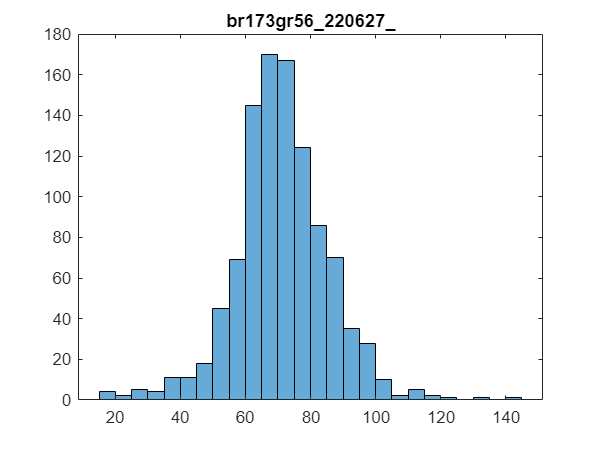

syl_min_win = 'cc'

day = 801

min_win_length = 47

max_win_length = 109

ind_min = 28

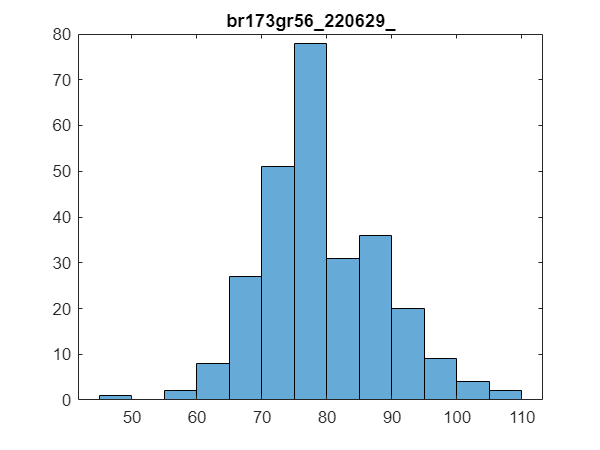

syl_min_win = 'c'

day = 802

min_win_length = 57

max_win_length = 109

ind_min = 39

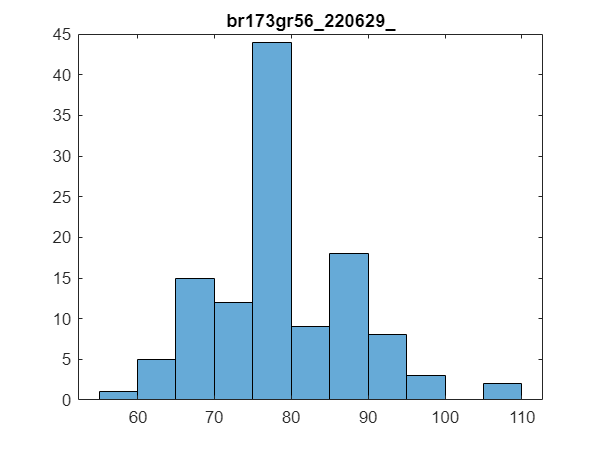

syl_min_win = 'b'

day = 803

min_win_length = 43

max_win_length = 111

ind_min = 415

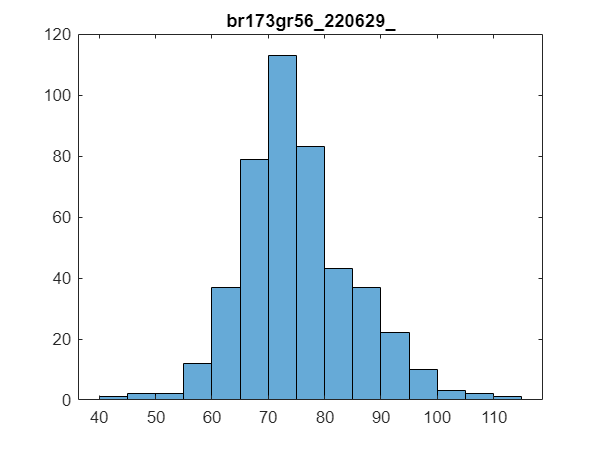

syl_min_win = 'f'

day = 811

min_win_length = 20

max_win_length = 127

ind_min = 449

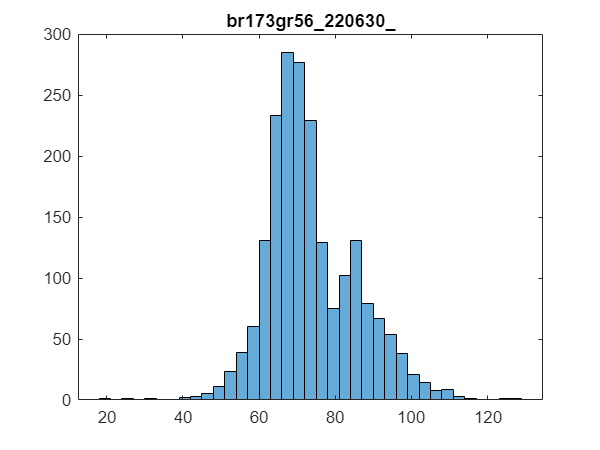

syl_min_win = 'c'

day = 153

min_win_length = 52

max_win_length = 97

ind_min = 368

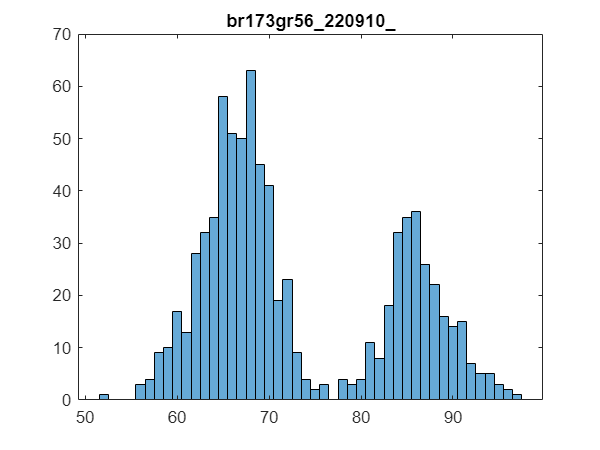

syl_min_win = 'g'

filename = 'spectrograms_br173gr56_syls_bcfgh_days_78_80_80_80_81_153_syldur_1_to_11.mat'

% directory where compiled data will be saved
warning('off')
savedir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects";
[spects_all_cut,labels_all,days_all] = compileSylSpects(birdname,syls,days,savedir,spect_params);

## Compile the matrix for feeding to tsne

% Create a spectrogram matrix of all trials padding with zero trials that are less than the maximum syllable duration
filename = 'spectrograms_br173gr56_syls_bcfgh_days_78_80_80_80_81_153_syldur_1_to_11.mat';
load(filename,'spect_uncut')
spects_all_zero_padded = spectsZeroPad(spect_uncut);
save(filename,"spects_all_zero_padded", '-append');

## Apply t-SNE with 3 dimensions

% Step 3: Prepare Data for t-SNE 
featureMatrix = spects_all_zero_padded; % spects_all or spects_all_zero_padded
perp = 25;
exg = 5;

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', 3,'Perplexity',perp,'Exaggeration',exg);
disp(loss)

    2.0834




% Save to existing file
tsneResult_zeroPadded_perp_25_exg_5 = tsneResult;
save(filename,'tsneResult_zeroPadded_perp_25_exg_5','-append')

## Plot t-SNE results in static 3D plot

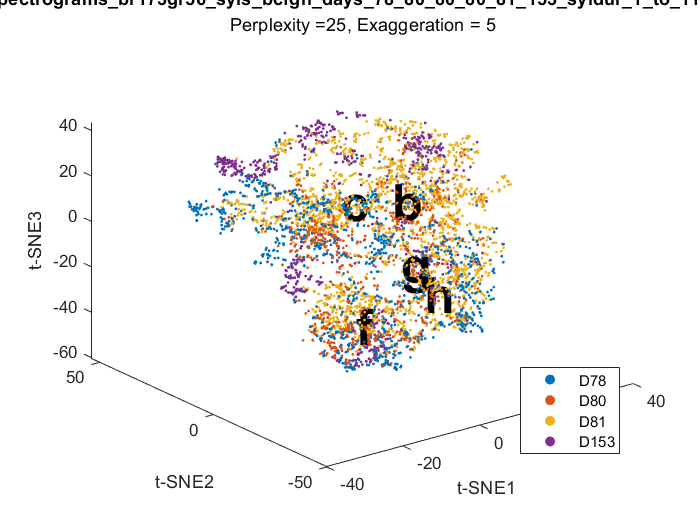

% Step 5: Assign unique colors based labels
plotLabel = days_all; % assign which labels for coloring and grouping

% Step 5b: Optional - assign unique colors based on second label
plotLabel2 = labels_all; % assign which labels for coloring and grouping
  
% Create 3D scatter plot
plot3Dtsne(tsneResult,plotLabel,plotLabel2)
title(filename,'Interpreter','latex')
subtitle(sprintf('Perplexity =%d, Exaggeration = %d', perp, exg))


% Save figure
savefig(gcf,[filename(1:end-4) '_zeropadded_perp_25_exg_5.fig'])

## Create video of tSNE results plotted through a sliding window

% Define the tSNE on the whole dataset
tsneResultAll = tsneResult;

% Fix the xyz axes based on the max values of the tsne results
ax_mins = [min(tsneResultAll(:, 1)), min(tsneResultAll(:, 2)), min(tsneResultAll(:, 3))];
ax_maxes = [max(tsneResultAll(:, 1)), max(tsneResultAll(:, 2)), max(tsneResultAll(:, 3))];

% Define parameters
bin_width = 1000;
bin_step = 50;

% Create a VideoWriter object
video_filename = [filename(1:end-4), '_MOVIE_bw' num2str(bin_width) '_step' num2str(bin_step) '.avi'];
video_writer = VideoWriter(video_filename);
video_writer.FrameRate = 5;

% Extract the base name for the directory
[folderPath, baseFileName, ~] = fileparts(video_filename);
newDir = fullfile(folderPath, baseFileName);
if ~exist(newDir)
    mkdir(newDir); % Create the new directory
end
cd(newDir)

open(video_writer);


% Assign fixed colors for all labels 
uniqueLabels = unique(labels_all);
numUniqueLabels = numel(uniqueLabels);
colors = lines(numUniqueLabels); % You can use any colormap you prefer

% Create a color map based on labels
labelColors = zeros(length(labels_all), 3);
for i = 1:numUniqueLabels
    labelColors(labels_all == uniqueLabels(i), :) = repmat(colors(i, :), sum(labels_all == uniqueLabels(i)), 1);
end


figure;

for start_row = 1:bin_step:(size(tsneResult, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult_bin = tsneResultAll(start_row:end_row, :);
    plotLabels_bin = labels_all(start_row:end_row);
    uniqueLabels_bin = unique(plotLabels_bin);
    numUniqueLabels_bin = numel(uniqueLabels_bin);
    labelColors_bin = labelColors(start_row:end_row,:);

    % Create 3D scatter plot
    hold on;
    for i = 1:numUniqueLabels_bin
        idx = plotLabels_bin == uniqueLabels_bin(i);
        scatter3(tsneResult_bin(idx, 1), tsneResult_bin(idx, 2), tsneResult_bin(idx, 3), 3, labelColors_bin(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult_bin(idx, :), 1);
        text_color = labelColors_bin(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels_bin(i), 'FontSize', 15, 'FontWeight', 'bold', 'Color', text_color);
    end
    hold off;

    % Set the axes limits
    xlim([ax_mins(1) ax_maxes(1)]);
    ylim([ax_mins(2) ax_maxes(2)]);
    zlim([ax_mins(3) ax_maxes(3)]);

    % Additional formatting
    title(['br177yw112']); % Adjust title as needed
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3); % Set the view to 3D
   

    % Pause for a short duration to create the animation effect
    pause(0.1);

    % Save the figure in .fig format only every 1000 trials
    if mod(start_row, 1000) == 1
        set(gcf,'Visible','On')
        figureFilename = sprintf('tSNE_perp%d_exg%d_%d.fig', perp,exg,start_row);
        savefig(gcf, figureFilename);
    end

    % Capture the current frame for the movie
    frame = getframe(gcf);
    writeVideo(video_writer, frame);

    % Clear the current figure for the next iteration
    clf;
end

% Close the video writer
close(video_writer);
cd ..